columns = 14;
rows = 13;

treasureX = randi([1 columns])

treasureX = 1

treasureY = randi([1 rows])

treasureY = 1

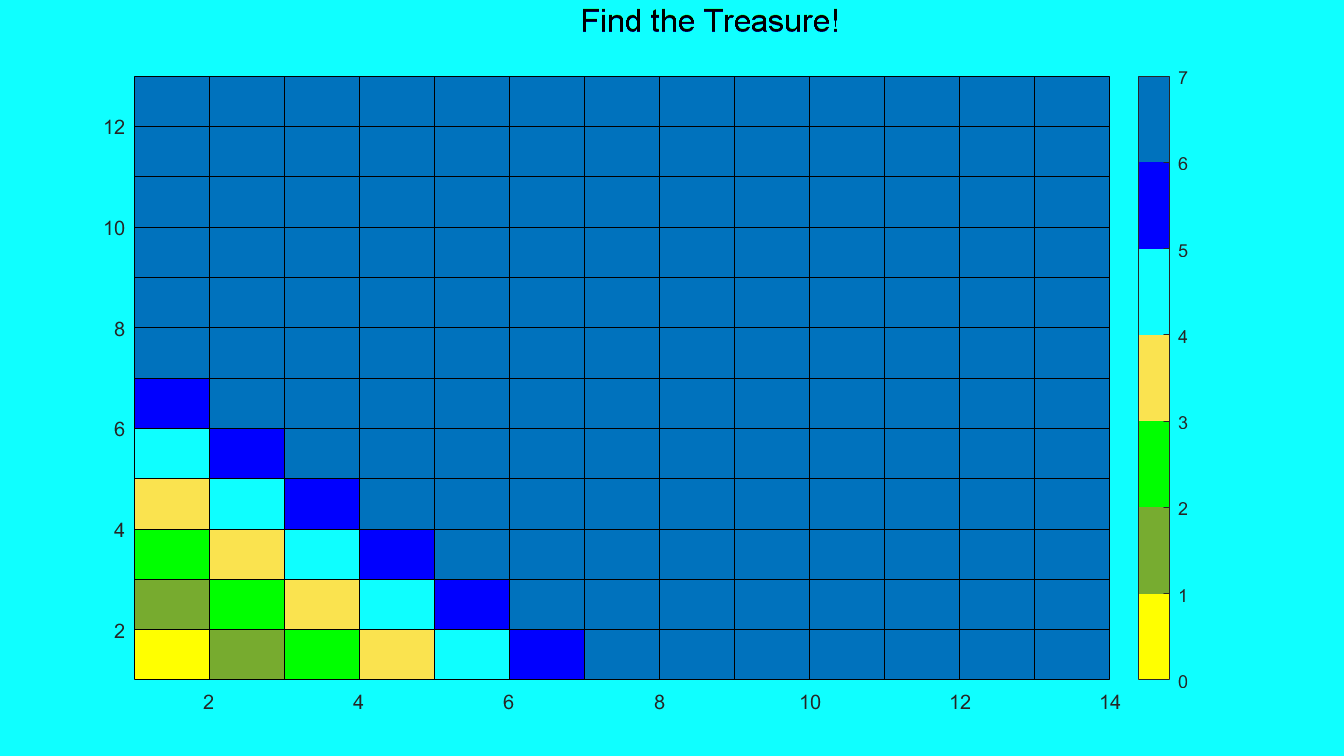


map = zeros(rows, columns);

map(map == 0) = NaN;

[x2,y2] = meshgrid(1:columns,1:rows);
taxiMatrix = abs(treasureY - y2(:))+ abs(treasureX - x2(:));

finalMap = reshape(taxiMatrix,rows,columns);

%Figure Window Setup
game = figure;
backgroundColor = [0.0588 1.0000 1.0000];
set(game,'Units','Normalized','Position',[0.15 0.20 0.70 0.70],'Color',backgroundColor,'Name','Treasure Hunt','NumberTitle','Off','Resize','Off');



%Text Title
talkHandle = uicontrol(game,'Style','text');
set(talkHandle,'Units','Normalized','Position',[0.43 0.9 0.2 0.10],'BackgroundColor',backgroundColor,'String','Find the Treasure!','FontSize',16);

%Add game board axes
axisHandle = axes;
set(axisHandle,'Units','Normalized','Position',[0.1 0.1 0.80 0.80],'XLim',[0 columns],'YLim',[0 rows],'XTick', 0:1:columns,'YTick', 0:1:rows,'Box','On');
grid on

%Display the game board in the background of the figure
%xOffset = -0.75;%Offset from edge of row/col
%yOffset = -0.50;%Offset from edge of row/col
%[x,y] = meshgrid(1 + xOffset:1:columns + xOffset,1 + yOffset:1:rows + yOffset);
%t = text(x(:),y(:),int2str(finalMap(:)), 'FontSize',8);
%set(t,'Color',[1 0 0]);

pcolor(map);

cmap = [1 1 0; 0.4667 0.6745 0.1882; 0 1 0;0.9804 0.8902 0.3137;0.0588 1 1; 0 0 1; 0 0.4471 0.7412];
colormap(cmap)
clim([0 7])
colorbar
hold on
pcolor(map)


playGame(treasureX,treasureY,map,finalMap)

You found the treasure!


function playGame(tX,tY,m,fm)
    guessX = input("Choose an X value:");
    guessY = input("Choose a Y value:");

    if(guessX == tX)&&(guessY == tY)
        %m(guessY,guessX) = fm(guessY,guessX);
        pcolor(fm)
        disp("You found the treasure!")
    else
        m(guessY,guessX) = fm(guessY,guessX);
        pcolor(m);
        playGame(guessX,guessY,m,fm);
    end
end